# **Lab 3**

## **Experiment 3.1**

**Part a)**

rng(1)
x = 1/sqrt(2) * randn(4096,1);
y = 1/sqrt(2) * 1i * randn(4096,1);
z = x + y;
h = Num;
output_conv = conv(z,h,'same');
Z = fftshift(fft(z,4096)/4096);
F_output_conv =fftshift(fft(output_conv,4096)/4096);

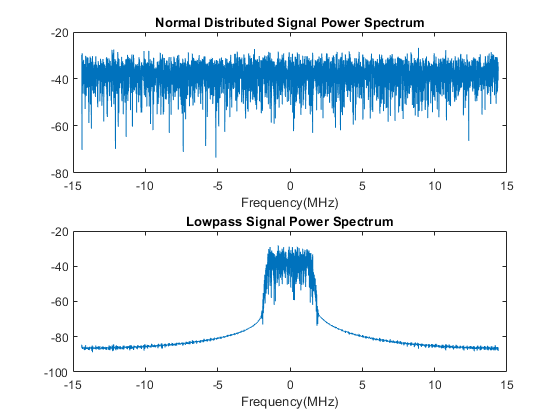

fs = 28.8e6;
N = 4096;
f = -fs/2 : fs/N: fs/2 - fs/N;
f=f/1e6;
figure
subplot(2,1,1)
plot(f,db(abs(Z)))
title('Normal Distributed Signal Power Spectrum')
xlabel('Frequency(MHz)')
subplot(2,1,2)
plot(f,db(abs(F_output_conv)))
title('Lowpass Signal Power Spectrum')
xlabel('Frequency(MHz)')

x_power = sum(abs(z).^2)/N;
disp("x_power : ");

x_power : 


disp(x_power)

    1.0122



x_baseband_power = sum(abs(output_conv).^2)/N;
disp("x_baseband_power : ");

x_baseband_power : 


disp(x_baseband_power)

    0.1139



bw = noisebw(h,1,121,fs);
disp("bw noise : ");

bw noise : 


disp(bw)

   3.3081e+06



**Part b)**

As already illustrated:

let x(t) be the lowpass process generated. let y(t) be the bandpass process.

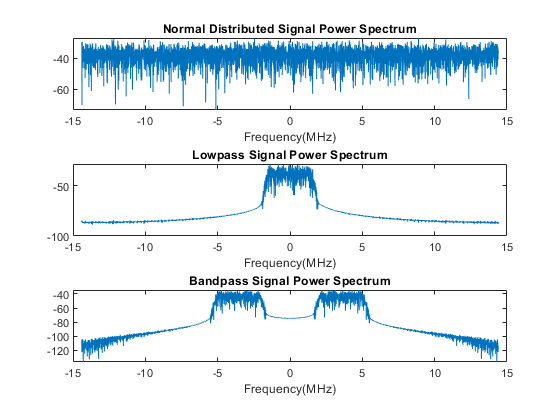

x = output_conv;
xi = real(x);
xq = imag(x);
fc = 3.57e6;
n = 0:N-1;
t = transpose(n/fs);
x_passband = xi.*cos(2*pi*fc.*t) - xq.*sin(2*pi*fc.*t);
Xf_passband = fftshift(fft(x_passband)/N);
figure
subplot(3,1,1)
plot(f,db(abs(Z)))
title('Normal Distributed Signal Power Spectrum')
xlabel('Frequency(MHz)')
subplot(3,1,2)
plot(f,db(abs(F_output_conv)))
title('Lowpass Signal Power Spectrum')
xlabel('Frequency(MHz)')
subplot(3,1,3)
plot(f,db(abs(Xf_passband)))
title('Bandpass Signal Power Spectrum')
xlabel('Frequency(MHz)')

x_power = sum(abs(z).^2)/N;
disp("x_power : ");

x_power : 


disp(x_power)

    1.0122



x_baseband_power = sum(abs(output_conv).^2)/N;
disp("x_baseband_power : ");

x_baseband_power : 


disp(x_baseband_power)

    0.1139



x_bandpass_power = sum(abs(x_passband).^2)/N;
disp("x_bandpass_power : ");

x_bandpass_power : 


disp(x_bandpass_power)

    0.0570



**Part c)**

% xl = (x_passband+1j*hilbert(x_passband)).*exp(-1j*2*pi*fc.*t);
xl = x_passband.*(2*cos(2*pi*fc.*t))+x_passband.*(-2*sin(2*pi*fc.*t));
filter1 = fir1(120,0.7e6*2/fs,'low');
filter2 = fir1(120,1.4e6*2/fs,'low');
filter3 = fir1(120,2.8e6*2/fs,'low');

h1 = filter1;
output_conv1 = conv(xl,h1,'same');
F_output_conv1 =fftshift(fft(output_conv1,4096)/4096);

h2 = filter2;
output_conv2 = conv(xl,h2,'same');
F_output_conv2 =fftshift(fft(output_conv2,4096)/4096);

h3 = filter3;
output_conv3 = conv(xl,h3,'same');
F_output_conv3 =fftshift(fft(output_conv3,4096)/4096);

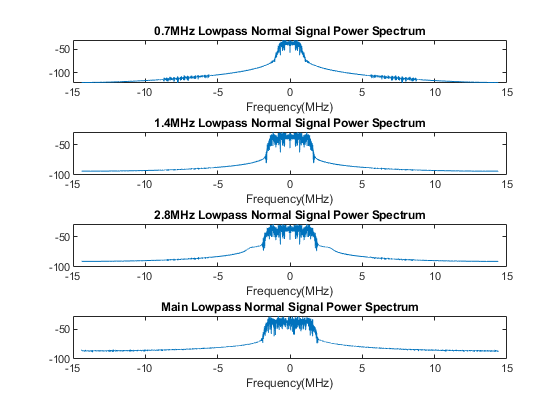

figure
subplot(4,1,1)
plot(f,db(abs(F_output_conv1)))
title('0.7MHz Lowpass Normal Signal Power Spectrum')
xlabel('Frequency(MHz)')
subplot(4,1,2)
plot(f,db(abs(F_output_conv2)))
title('1.4MHz Lowpass Normal Signal Power Spectrum')
xlabel('Frequency(MHz)')
subplot(4,1,3)
plot(f,db(abs(F_output_conv3)))
title('2.8MHz Lowpass Normal Signal Power Spectrum')
xlabel('Frequency(MHz)')
subplot(4,1,4)
plot(f,db(abs(F_output_conv)))
title('Main Lowpass Normal Signal Power Spectrum')
xlabel('Frequency(MHz)')

x_baseband_power = sum(abs(output_conv).^2)/N;
disp("x_baseband_power : ");

x_baseband_power : 


disp(x_baseband_power)

    0.1139



x_baseband_0p7_power = sum(abs(output_conv1).^2)/N;
disp("x_baseband_0p7_power : ");

x_baseband_0p7_power : 


disp(x_baseband_0p7_power)

    0.0474



x_baseband_1p4_power = sum(abs(output_conv2).^2)/N;
disp("x_baseband_1p4_power : ");

x_baseband_1p4_power : 


disp(x_baseband_1p4_power)

    0.0995



x_baseband_2p8_power = sum(abs(output_conv3).^2)/N;
disp("x_baseband_2p8_power : ");

x_baseband_2p8_power : 


disp(x_baseband_2p8_power)

    0.1184

